# Root Finding Methods

Numerical solution of f(x)=0

 |- Brackting methods

 |       |- Bisection

 |       |- Regula Falsi method (False Position) 

 |

 |- Open methods 

 |       |- Fixed-point method

 |       |- Newton's mehod

 |       |- Secant method

 |

 |- MATLAB function fzero, roots

# **Bisection Method**

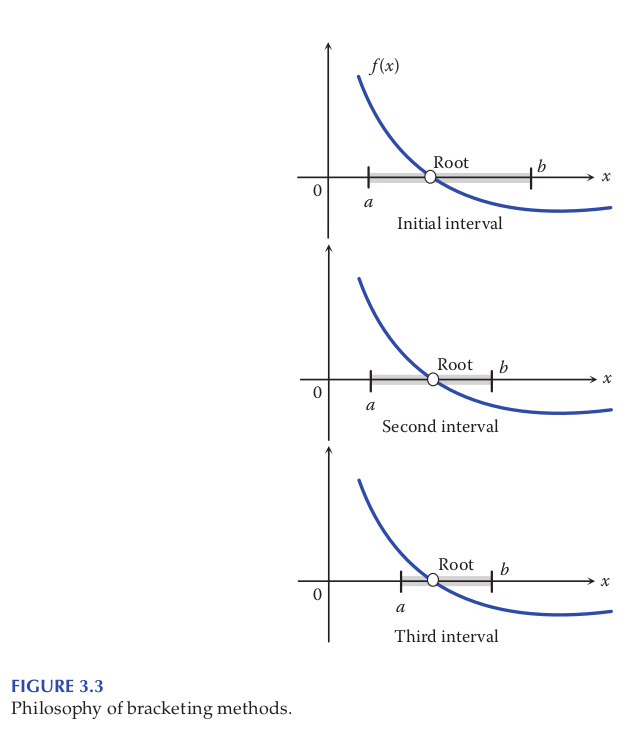

**Ex1 page22**

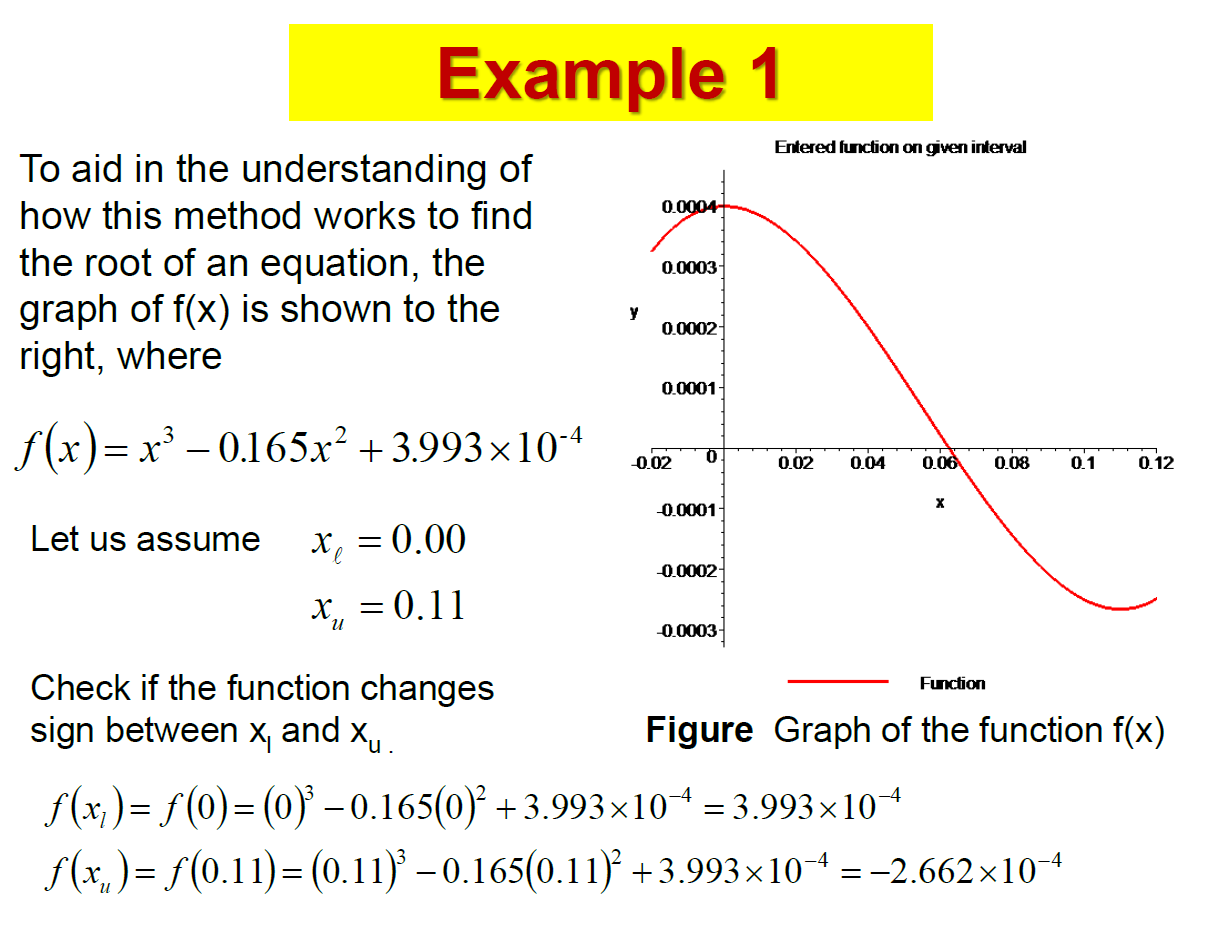

clear;clc
f = @(x) x.^3-0.165*x.^2+3.99*10^-4;
% ขอบเขต a b             0.0 0.11
% จำนวนรอบในการวงซ้ำ      20,[]
% ค่าความผิดพลาดที่ยอมรับได้  0.01
disp('function bisection')

function bisection


bisection(f,0.00,0.11)

i = 1

b = 0.0825

i = 2

b = 0.0688

i = 3

i = 4

b = 0.0653

i = 5

b = 0.0636

i = 6

b = 0.0627

i = 7

i = 8

b = 0.0625

i = 9

b = 0.0624

i = 10

b = 0.0624

i = 11

i = 12

b = 0.0623

i = 13

i = 14

i = 15

i = 16

b = 0.0623

i = 17

i = 18

b = 0.0623

i = 19

i = 20

i = 21

i = 22

i = 23

i = 24

i = 25

i = 26

b = 0.0623

i = 27

i = 28

i = 29

i = 30

b = 0.0623

i = 31

i = 32

b = 0.0623

i = 33

b = 0.0623

i = 34

b = 0.0623

i = 35

b = 0.0623

i = 36

b = 0.0623

i = 37

b = 0.0623

i = 38

b = 0.0623

i = 39

i = 40

ans = 0.0623

disp('function Bisection')

function Bisection


Bisection(f,0,0.11,[],0.01)

 k      a      b      c      (b-a)/2
  1      0.000000   0.110000   0.055000   0.055000
  2      0.055000   0.110000   0.082500   0.027500
  3      0.055000   0.082500   0.068750   0.013750
  4      0.055000   0.068750   0.061875   0.006875


ans = 0.0619

disp('function Bisct')

function Bisct


Bisct(f,0,0.11,0.01,20)

ans = 0.0619

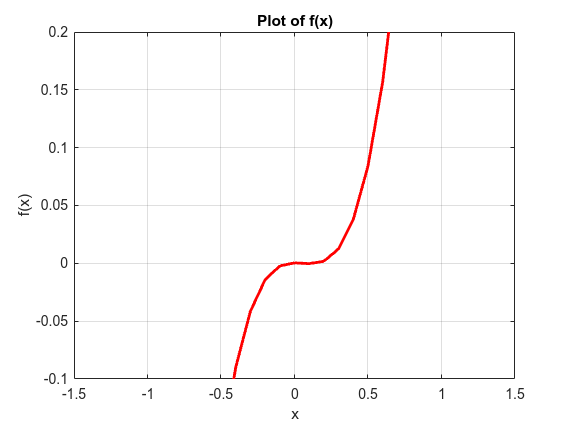


%plot graph
x = -1:0.1:1;
plot(x, f(x), 'LineWidth', 2, 'Color', 'red'); % Set line width and color
xlabel('x');
ylabel('f(x)');
title('Plot of f(x)');
xlim([-1.5 1.5]); % Adjust x-axis limits
ylim([-0.1 0.2]); % Adjust y-axis limits
grid on;

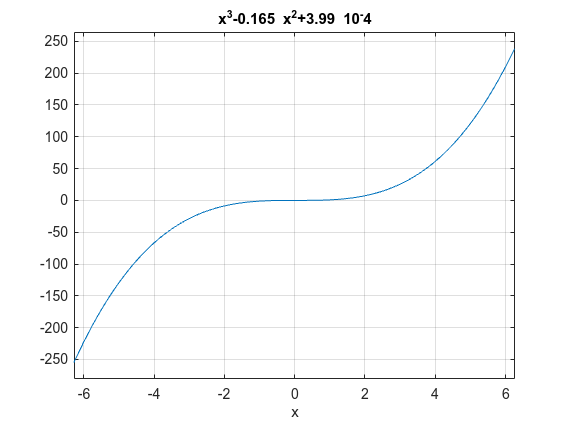


ezplot('x^3-0.165*x^2+3.99*10^-4')
grid on;


ezplot(f)
grid on;

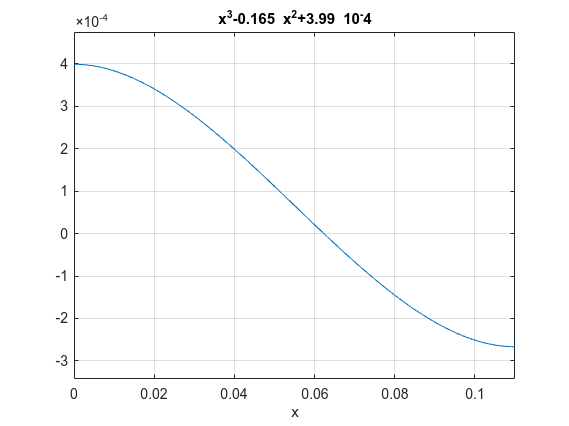


ezplot(f,[0 0.11])
grid on;

**Built-in function  (fzero)**

fzero(f,[0,0.11])

ans = 0.0623

# Regula Falsi Method(Method of False Position)

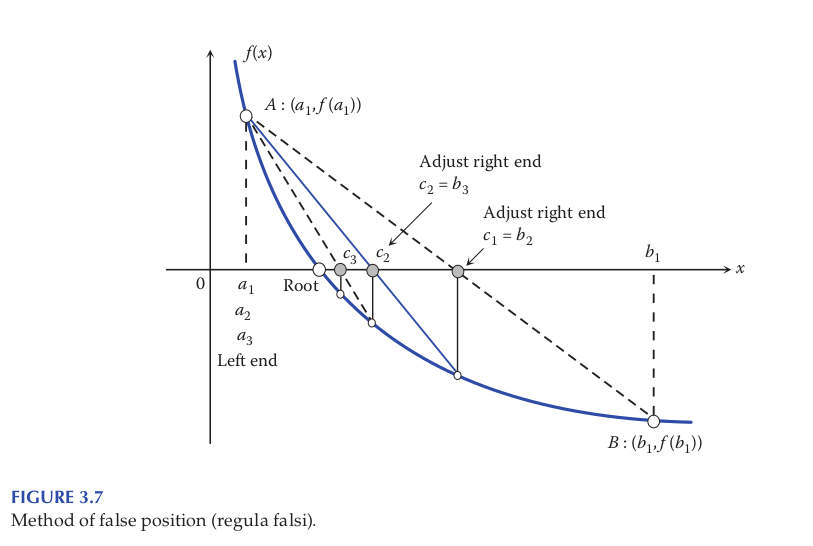

Ex

clear;clc;clf
f = @(x)(x*cos(x)+1);
[r, k] = RegulaFalsi(f, -2, 4, [], 1e-2)

 k    a       b
 1      -2.000000   4.000000
 2       1.189493   4.000000
 3       1.189493   2.515720
 4       1.960504   2.515720


r = 2.0738

k = 4


ezplot(f)

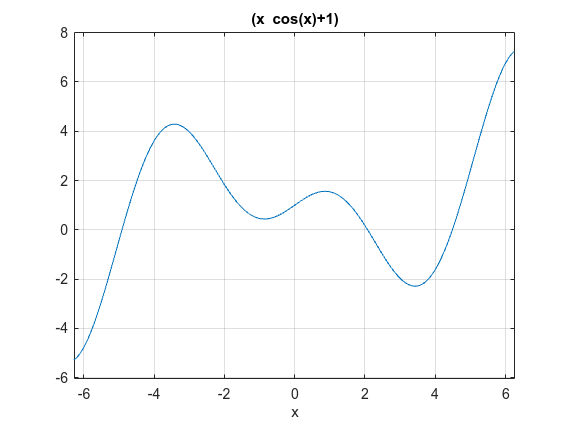

grid on;

bulit-in function 

fzero(f,[-2,4.11])

ans = 2.0739

# fixed-point Method

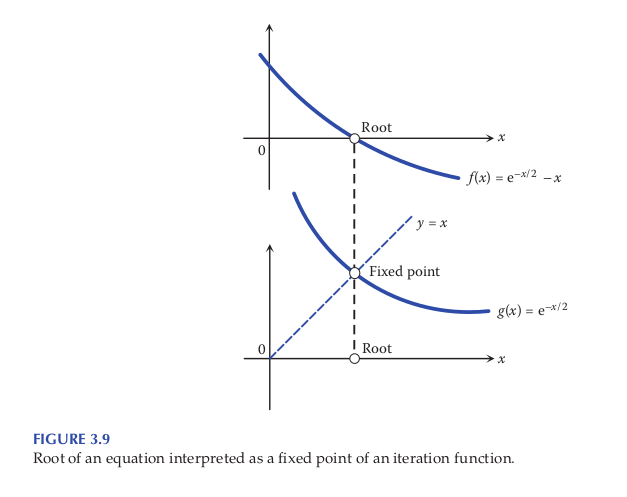

clear;clc;clf
g = @(x)(2^(-x));
ezplot(g,[0,2])

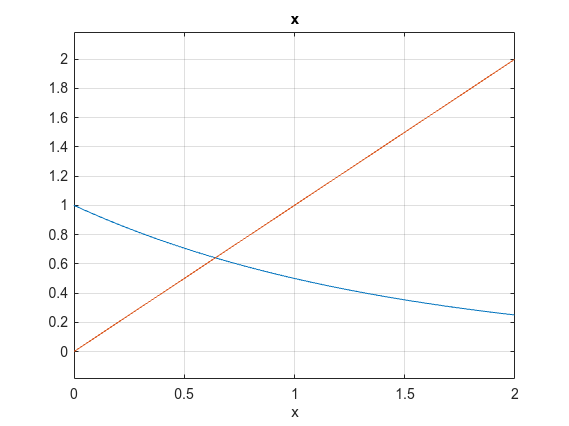

hold on
grid on;
syms x
ezplot(x,[0,2])

[r, n] = FixedPoint(g, 0)

r = 0.6412

n = 13

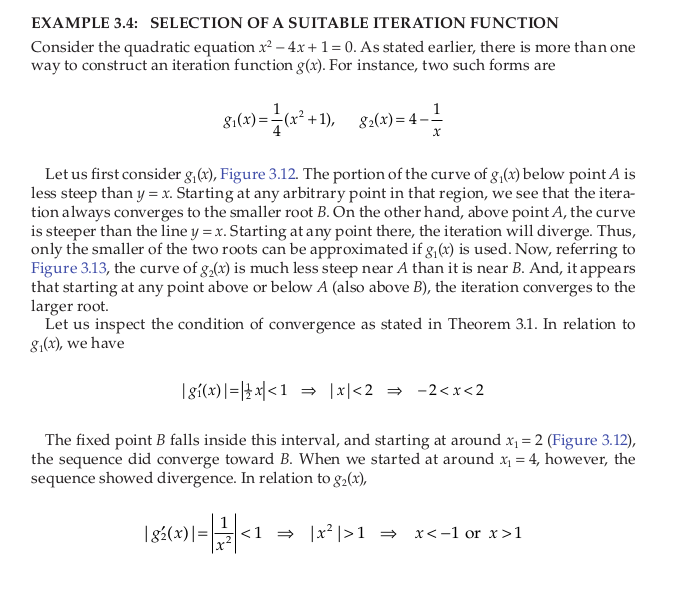

clear;clc;clf
f = @(x)(x^2-4*x+1);
g1 = @(x)((x^2+1)/4); 
g2 = @(x)(4-1/x);
[r1, n] = FixedPoint(g1, 2)

r1 = 0.2680

n = 8

[r2, n] = FixedPoint(g2, 0.3)

r2 = 3.7320

n = 7

buil-in function

disp('buil-in function')

buil-in function


roots([1 -4 1])

ans =     3.7321
    0.2679


plot

ezplot(f)

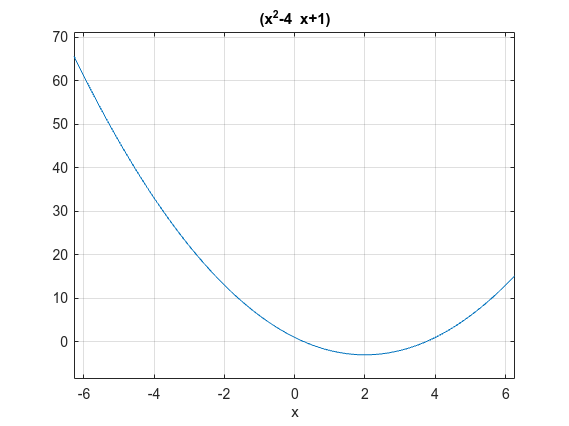

grid on;

# Newton’s Method (Newton–Raphson Method)

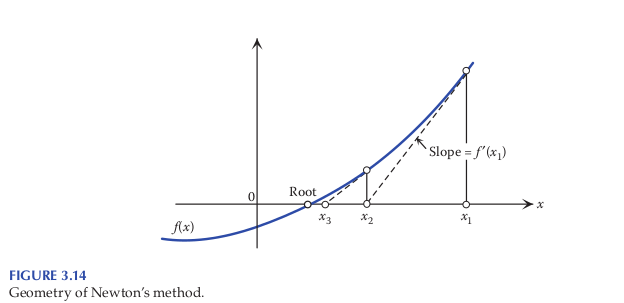

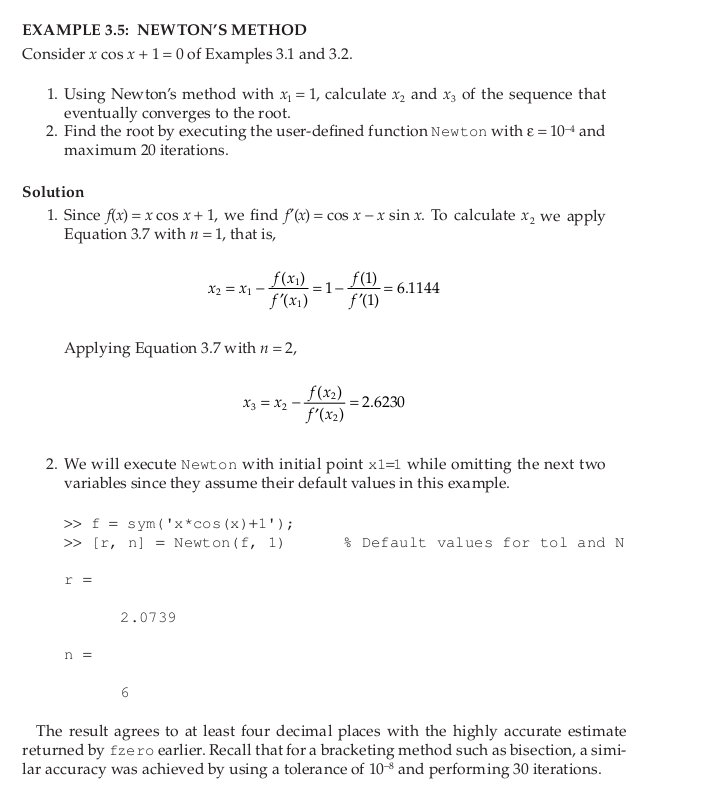

clear;clc;clf
syms x
f = x*cos(x)+1;
[r, n] = Newton(f, 1)   % Default values for tol and N

r = 2.0739

n = 6

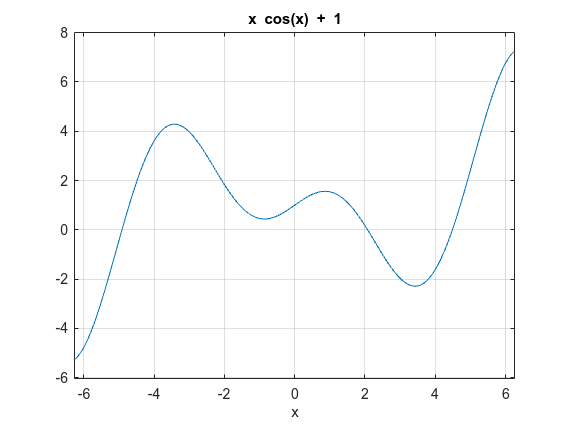

%buit in function

ezplot(f)
grid on;


f1 =@(x)(x*cos(x)+1)

f1 = function_handle with value:
    @(x)(x*cos(x)+1)


Bisection(f1,2,2.5)

 k      a      b      c      (b-a)/2
  1      2.000000   2.500000   2.250000   0.250000
  2      2.000000   2.250000   2.125000   0.125000
  3      2.000000   2.125000   2.062500   0.062500
  4      2.062500   2.125000   2.093750   0.031250
  5      2.062500   2.093750   2.078125   0.015625
  6      2.062500   2.078125   2.070312   0.007812
  7      2.070312   2.078125   2.074219   0.003906
  8      2.070312   2.074219   2.072266   0.001953
  9      2.072266   2.074219   2.073242   0.000977
 10      2.073242   2.074219   2.073730   0.000488
 11      2.073730   2.074219   2.073975   0.000244
 12      2.073730   2.073975   2.073853   0.000122
 13      2.073853   2.073975   2.073914   0.000061


ans = 2.0739

fzero(f1,[1,3])

ans = 2.0739

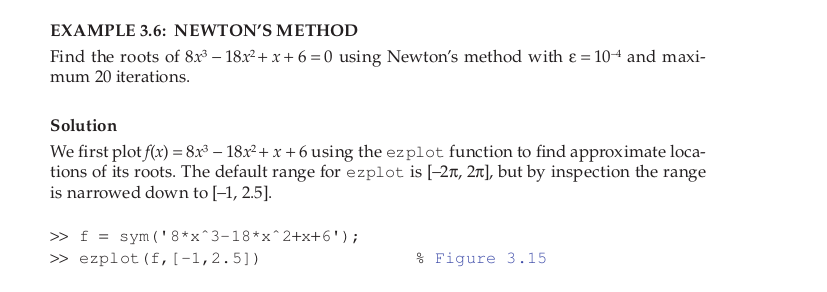

clc;clear;clf
syms x
f = 8*x^3-18*x^2+x+6

$$f = 8\,x^{3}-18\,x^{2}+x+6$$

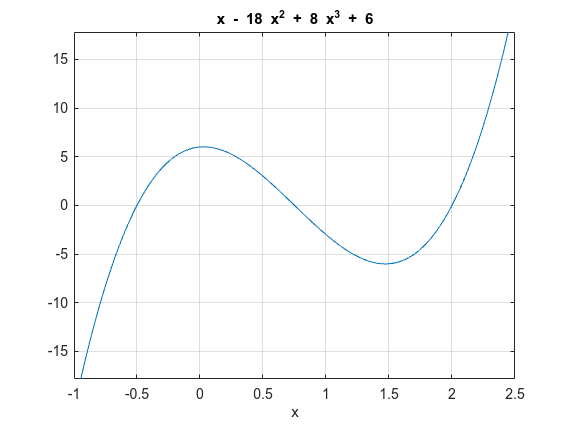


ezplot(f,[-1,2.5])
grid on;

[r1, n1] = Newton(f, -1)   % f was defined (symbolically) earlier

r1 = -0.5000

n1 = 5

[r2, n2] = Newton(f, 0.5)

r2 = 0.7500

n2 = 3

[r3, n3] = Newton(f, 1.5)

r3 = 2.0000

n3 = 10


roots([8 -18 1 6])

ans =     2.0000
    0.7500
   -0.5000


# Modified Newton’s Method for Roots with Multiplicity 2 or Higher

[r, n] = Newton(f, 0)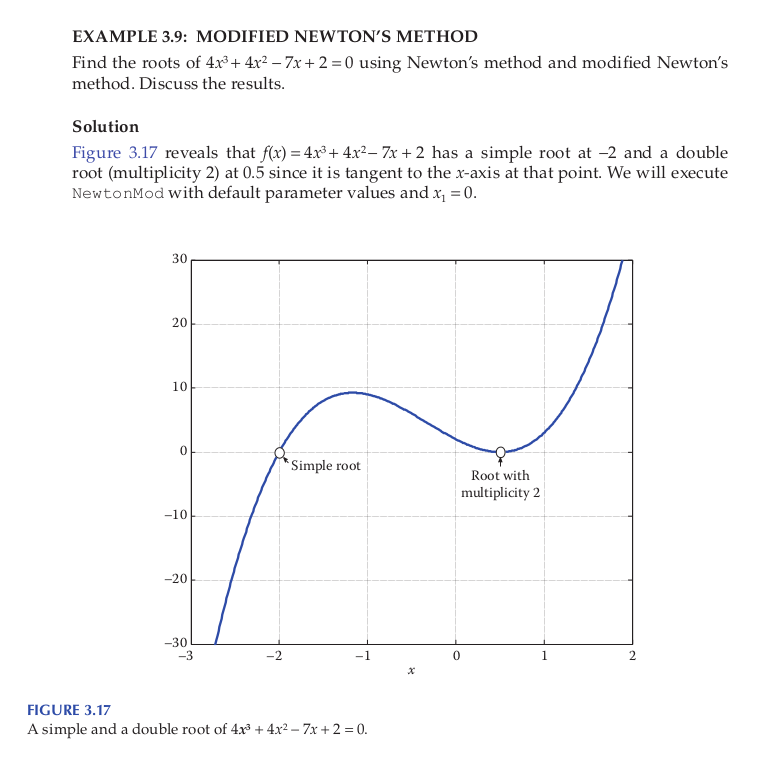

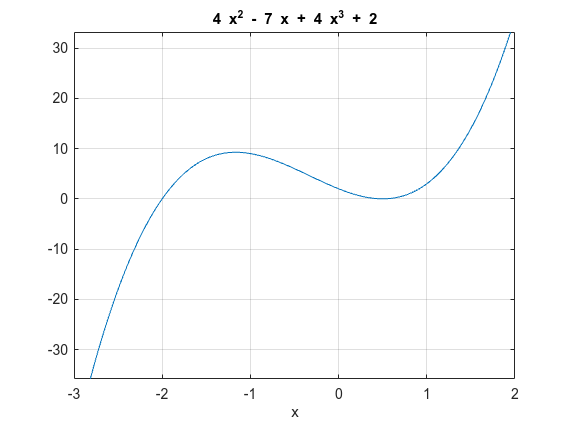

clear;clc;clf
syms x
f = 4*x^3+4*x^2-7*x+2;
ezplot(f,[-3,2])
grid on;

[r, n] = NewtonMod(f, 0)

r = 0.5000

n = 4

[r, n] = Newton(f, 0)

r = 0.4999

n = 12

% n ต่างกันเยอะอยู่(จำนวนรอบที่ลู่เข้า)

[r, n] = Newton(f, -3)

r = -2.0000

n = 5

# Secant Method

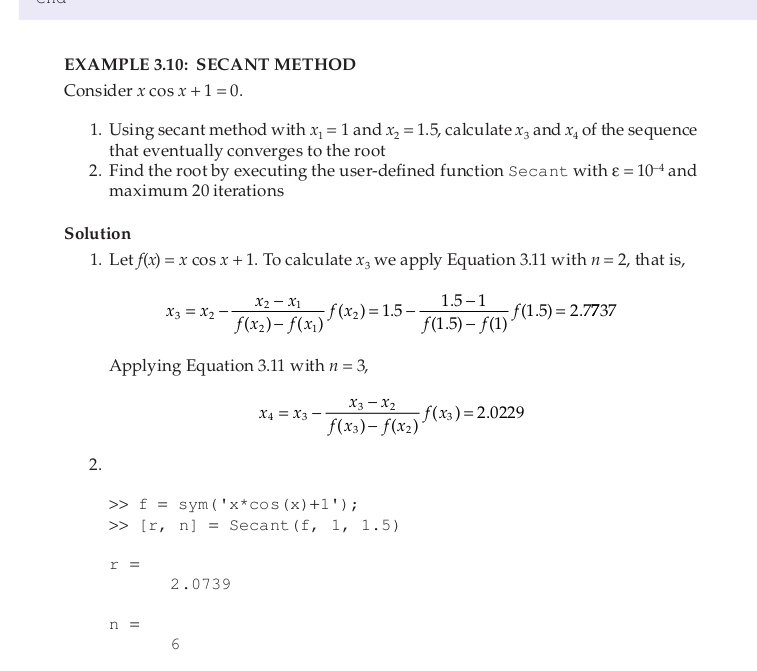

clear;clc;clf
syms x
f = x*cos(x)+1;
[r, n] = Secant(f, 1, 1.5)

r = 2.0739

n = 6